%L2.a. State Space Analysis

% Problem 1
% Aim: To represent transfer function in state space form and vice versa
% Also to obtain step response of SISO system
% Consider a plant transfer function
% G(s)=(s^3+5s^2+4s+6)/(4s^3+7s^2+12s+9)

% Transfer function coefficients
num1=[1 5 4 6];
den1=[4 7 12 9];
% Transfer function to state space conversion
[A,B,C,D]=tf2ss(num1,den1)

A =    -1.7500   -3.0000   -2.2500
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =     0.8125    0.2500    0.9375


D = 0.2500

% State space to transfer function conversion
[num3,den3]=ss2tf(A,B,C,D)

num3 =     0.2500    1.2500    1.0000    1.5000


den3 =     1.0000    1.7500    3.0000    2.2500


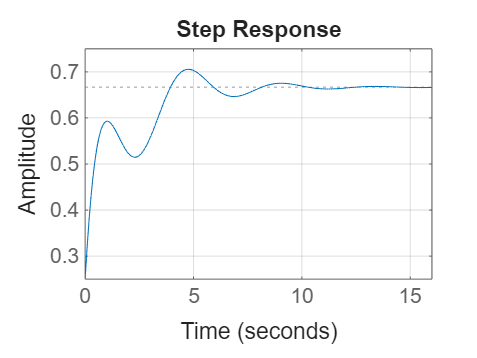

% Step response from state space model
figure(1)
step(A,B,C,D)
grid on
title('Step Response')

%L2.a. State Space Analysis

% Problem 2
% MIMO system time domain response

% State space matrices
A=[0 1;-25 -4];
B=[1 1;0 1];
C=[1 0;0 1];
D=[0 0;0 0];

% Transfer functions corresponding to input u1
[num1,den1]=ss2tf(A,B,C,D,1)

num1 =      0     1     4
     0     0   -25


den1 =     1.0000    4.0000   25.0000


% Transfer functions corresponding to input u2
[num2,den2]=ss2tf(A,B,C,D,2)

num2 =          0    1.0000    5.0000
         0    1.0000  -25.0000


den2 =     1.0000    4.0000   25.0000


% Eigenvalues of A matrix
eig(A)

ans =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i


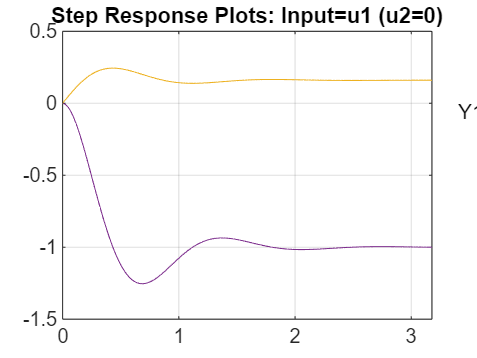

% Step response for input u1 (u2=0)
figure(2)
[y1,y2,t]=step(A,B,C,D,1);
plot(t,y1,t,y2)
grid on
title('Step Response Plots: Input=u1 (u2=0)')
text(3.4,-0.06,'Y1')
text(3.4,1.4,'Y2')

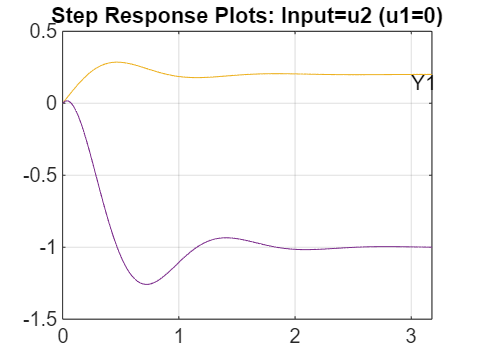

% Step response for input u2 (u1=0)
figure(3)
[y1,y2,t]=step(A,B,C,D,2);
plot(t,y1,t,y2)
grid on
title('Step Response Plots: Input=u2 (u1=0)')
text(3,0.14,'Y1')
text(2.8,1.1,'Y2')

%L2.a. State Space Analysis

% Problem 3
% Diagonalization of A matrix in Controllable Canonical Form
% Determine Jordan canonical form and verify system properties

% State space matrices
A=[0 1 0;0 0 1;-6 -11 -6];
B=[0;0;2];
C=[1 0 0];
D=[0];
% Eigenvalues of A
L=eig(A)

L =    -1.0000
   -2.0000
   -3.0000


% Van der Monde transformation matrix
P=[1 1 1;
   L(1) L(2) L(3);
   L(1)^2 L(2)^2 L(3)^2];
% Inverse of transformation matrix
PI=inv(P);
% Diagonalized state model
ASTILDA=PI*A*P

ASTILDA =    -1.0000   -0.0000   -0.0000
   -0.0000   -2.0000   -0.0000
    0.0000   -0.0000   -3.0000


BSTILDA=PI*B

BSTILDA =     1.0000
   -2.0000
    1.0000


CSTILDA=C*P

CSTILDA =      1     1     1


DSTILDA=D

DSTILDA = 0

% Eigenvalues of transformed matrix
L1=eig(ASTILDA)

L1 =    -1.0000
   -2.0000
   -3.0000


% Determinants
DETA=det(A)

DETA = -6

DETSTILDA=det(ASTILDA)

DETSTILDA = -6.0000

% Traces
TRA=trace(A)

TRA = -6

TRASTILDA=trace(ASTILDA)

TRASTILDA = -6.0000

% Transfer function from original state model
[num,den]=ss2tf(A,B,C,D);
S1=tf(num,den)


S1 =
 
            2
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


% Transfer function from transformed state model
[num1,den1]=ss2tf(ASTILDA,BSTILDA,CSTILDA,DSTILDA);
S2=tf(num1,den1)


S2 =
 
            2
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties
